# DiD Analysis with DiD-Toolbox

This script performs a Difference-in-Differences analysis using the `did-toolbox` for data simulation and for the Two-Way Fixed Effects (TWFE) estimation.

## 1. Simulation via did-toolbox

We use `did.genDIDdata` to create a balanced panel. Parameters:

- *startPeriod=StartP* implies treatment is active for periods >= StartP

- *treatType="constant"* means once treated, always treated with constant effect.

% Simulation Parameters
rng(42);
N = 100;         % number of individuals/units
T = 10;          % 10 periods
percTreated = 0.5;
ATT_true = 5.0;  % true treatment impact for treated
StartP = 6;      % Treatment starts at period 6

% Generate Panel Data
data = did.genDIDdata(T, N, percTreated, ...
    'startPeriod', StartP, ...
    'endPeriod', T, ...
    'ATT', ATT_true, ...
    'treatType', "constant");

% Display first few rows
head(data)

    id    time       y        D    g    eventTime     i_FE        t_FE      everTreated    ATT
    __    ____    ________    _    _    _________    _______    ________    ___________    ___

    1      1       0.94925    0    6       -5        -1.4209     0.40204         1          0 
    1      2       -3.6435    0    6       -4        -1.4209     -1.2375         1          0 
    1      3       0.72533    0    6       -3        -1.4209     0.19333         1          0 
    1      4      -0.74733    0    6       -2        -1.4209     0.61168         1          0 
    1      5       -3.2676    0    6       -1        -1.4209     0.36643         1       

## 2. Method 1: Simple Difference in Means

We compare mean outcomes in Post vs Pre windows for Treated vs Control:

- Pre-window: time < StartP

- Post-window: time >= StartP

data.Post = double(data.time >= StartP);

% Calculate Conditional Means
% We average over all observations in the respective windows
mean_Treat_Post = mean(data.y(data.everTreated==1 & data.Post==1));
mean_Treat_Pre  = mean(data.y(data.everTreated==1 & data.Post==0));
mean_Control_Post = mean(data.y(data.everTreated==0 & data.Post==1));
mean_Control_Pre  = mean(data.y(data.everTreated==0 & data.Post==0));

% Difference-in-Differences
DiD_Means = (mean_Treat_Post - mean_Treat_Pre) - (mean_Control_Post - mean_Control_Pre);

disp("Means DiD Estimate: " + string(DiD_Means));

Means DiD Estimate: 5.0422


## 3. Method 2: OLS (Classic Interaction)

We fit the model $Y = \beta_0 + \beta_1 Treat + \beta_2 Post + \delta (Treat \times Post) + \epsilon$.


% Prepare dummy variables
data.Treat = double(data.everTreated);
% data.Post is already created above

% Run OLS
lm_ols = fitlm(data, 'y ~ Treat * Post');

% Extract the interaction coefficient robustly
coeffs_ols = lm_ols.Coefficients;
disp(coeffs_ols); % DEBUG: Print table

                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)     0.54303    0.14035     3.8692    0.00011628
    Post            0.25093    0.19848     1.2643       0.20643
    Treat          -0.25553    0.19848    -1.2874       0.19825
    Post:Treat       5.0422    0.28069     17.964      1.02e-62




interactionName = "Treat:Post";
if ~any(strcmp(coeffs_ols.Properties.RowNames, interactionName))
    interactionName = "Post:Treat";
end

if any(strcmp(coeffs_ols.Properties.RowNames, interactionName))
    DiD_OLS = coeffs_ols.Estimate(interactionName);
else
    disp("Warning: Interaction term not found (using NaN).");
    DiD_OLS = NaN;
end

disp("OLS DiD Estimate: " + string(DiD_OLS));

OLS DiD Estimate: 5.0422


## 4. Method 3: TWFE via did-toolbox

We use the `did.fit` wrapper to easily access the TWFE /two-way-fixed effects) estimator with clustered standard errors.


% Create Dataset object
ds = did.Dataset.fromTable(data, ...
    'idVar', "id", ...
    'timeVar', "time", ...
    'yVar', "y", ...
    'dVar', "D");


[DataDesc] Units = 100 | Periods = 10 | Nobs = 1000 | Balanced Units = 100 (100.0%)
[DataDesc] Ever-treated = 50 (50.0%) | Never-treated = 50 (50.0%) | Leavers = 0 (0.0% of ever)
Cohorts (first 6 rows):
    cohort_label    N_units    Share    N_leavers    ShareLeaversAmongCohort    FirstTreat_time
    ____________    _______    _____    _________    _______________________    _______________

        "6"           50        0.5         0                   0                      6       

Outcome Y (overall) – N/Mean/SD/Min/P25/Median/P75/Max:
     N       Mean       SD        Min        P25       Median     P75       Max  
    ____   

% Instantiate TWFE Estimator via did.fit to enable SEs
% We use "twfe" method and request "clustered" standard errors.
res_twfe = did.fit("twfe", ds, clusters=["id","time"]);

[TWFE] Standard errors clustered by id, time 
[TWFE]
  1×5 table

    Name    Estimate      SE       tStat      pValue  
    ____    ________    _______    _____    __________

    "D"      5.0422     0.20001    25.21    1.1689e-09




% Extract Result
DiD_TWFE = res_twfe.ATT;
disp("TWFE DiD Estimate: " + string(DiD_TWFE));

TWFE DiD Estimate: 5.0422


% Display full coefficient table included in result
if isfield(res_twfe, 'coef')
    disp(res_twfe.coef);
end

    Name    Estimate      SE       tStat      pValue  
    ____    ________    _______    _____    __________

    "D"      5.0422     0.20001    25.21    1.1689e-09



## 5. Comparison

Bringing all results together.

% OLS SE
if exist('interactionName', 'var') && any(strcmp(coeffs_ols.Properties.RowNames, interactionName))
    se_ols = coeffs_ols.SE(interactionName);
else
    se_ols = NaN;
end

% TWFE SE
se_twfe = res_twfe.SE;

results_table = table(...
    ["Means"; "OLS"; "TWFE"], ...
    [DiD_Means; DiD_OLS; DiD_TWFE], ...
    [NaN; se_ols; se_twfe], ...
    'VariableNames', ["Method", "Estimate", "SE"]);

disp(results_table);

    Method     Estimate      SE   
    _______    ________    _______

    "Means"     5.0422         NaN
    "OLS"       5.0422     0.28069
    "TWFE"      5.0422     0.20001



## 6. Event Study Plot (Parallel Trends)

Visualization of average outcome $Y$ by event time, differentiated by Treated vs Control.

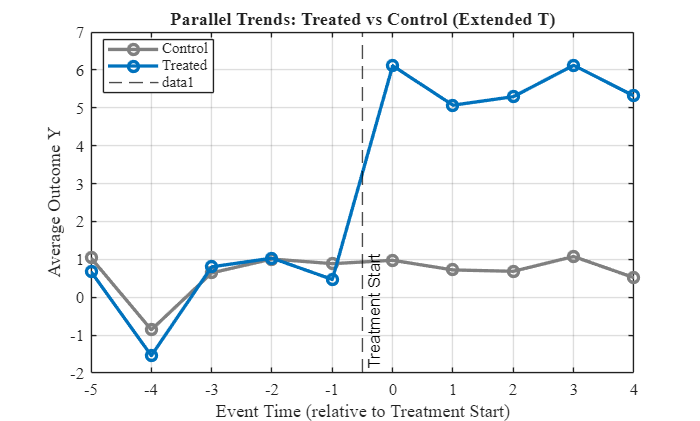

% Treatment starts at defined StartP.
g_ref = StartP;

% Calculate Event Time relative to g_ref
% k < 0 (Pre), k >= 0 (Post)
data.EventTime_Plot = data.time - g_ref;

% Aggregate Mean Y by (Group, EventTime)
stats = groupsummary(data, ["EventTime_Plot", "everTreated"], "mean", "y");

% Separate for plotting
stats_T = stats(stats.everTreated == 1, :);
stats_C = stats(stats.everTreated == 0, :);

% Plot
figure('Name', 'Parallel Trends Check (More Periods)', 'Color', 'w');
hold on;

% Plot Control Group
plot(stats_C.EventTime_Plot, stats_C.mean_y, '-o', ...
    'LineWidth', 2, 'Color', [0.5, 0.5, 0.5], ...
    'DisplayName', 'Control');

% Plot Treated Group
plot(stats_T.EventTime_Plot, stats_T.mean_y, '-o', ...
    'LineWidth', 2, 'Color', [0, 0.4470, 0.7410], ...
    'DisplayName', 'Treated');

% Add Reference Line for Treatment Start
xline(-0.5, '--k', 'Treatment Start', 'LabelVerticalAlignment', 'bottom');

xlabel('Event Time (relative to Treatment Start)');
ylabel('Average Outcome Y');
title('Parallel Trends: Treated vs Control (Extended T)');
legend('Location', 'best');
grid on;
box on;

hold off;